## Centro de pressão de uma vela

O centro de pressão de uma vela com a forma triangular com vértices (0,0) (2,1) e (0,5). Retirado de Larson, R. et al.(2006) Cálculo - Volume 2(oitava edição). McGraw-Hill.

syms x y;
f = @(x) x./2;
g = @(x) 5-2.*x;


Depois de definirmos as funções, podemos fazer o gráfico destas.


fplot(f,[0,2]);
hold on;
axis on;
fplot(g,[0,2]);% Desenhar as funções


Para calcular a massa da vela assumindo que a densidade/massa específica é igual à distância de cada ponto ao eixo dos xx's.

Massa = integral2(@(x,y) y,0,2,f,g);
display(Massa);% calcular a massa

Massa = 10.0000

Para calcular o centro de massa, teremos de calcular os primeiros momentos e depois dividi-los pela Massa.

M_x = integral2(@(x,y) x.*y,0,2,f,g);

M_y = integral2(@(x,y) y.^2,0,2,f,g);% calcular os primeiros momentos

centro_de_massa = 1/Massa.*[M_x , M_y];

display(centro_de_massa);

centro_de_massa =     0.5833    2.5833


% inserir centro de massa
plot(centro_de_massa(1), centro_de_massa(2),'o');


Para finalizar que tal ver o efeito da inércia numa rotação em torno do eixo dos yy's.

% Calcular momento de inércia (massa)*distância^2

I_y = integral2(@(x,y) y.*x.^2,0,2,f,g);
display(I_y);

I_y = 5.3333

E se a reta onde ocorre o eixo de rotação fosse uma outra reta vertical x=a?

Quais seriam os momentos de inércia à direita e à esquerda? Quando é que seriam iguais? E qual seria o valor de a para atingirmos o momento de inércia mínimo?

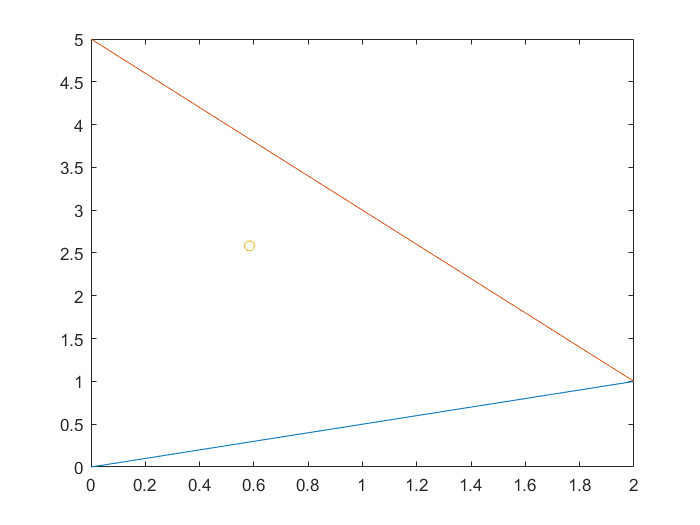

ind = 0:0.01:2;
I_values = [];
I_values_2 = [];
I_values_3 = [];
for i=1:size(ind,2)
    I_values(i) = integral2(@(x,y) y.*(x-ind(i)).^2,0,ind(i),f,g);
    I_values_2(i) = integral2(@(x,y) y.*(x-ind(i)).^2,ind(i),2,f,g);
    I_values_3(i) = integral2(@(x,y) y.*(x-ind(i)).^2,0,2,f,g);
end
hold off;

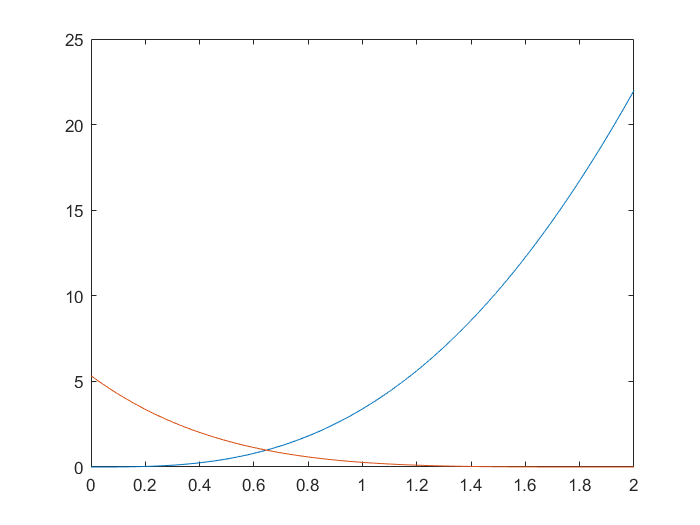

plot(ind,I_values);
hold on;
plot(ind,I_values_2);
diff = abs(I_values-I_values_2);
[I_min,i_min] = min(diff);
hold off;

disp([ind(i_min),I_min]);

    0.6500    0.0305



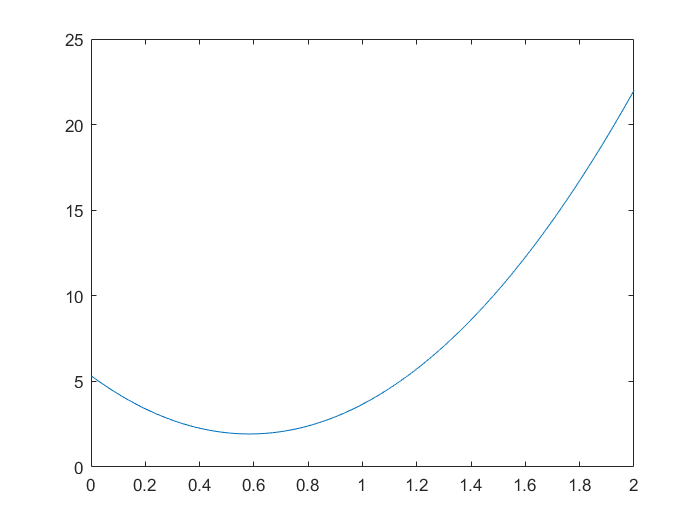

plot(ind,I_values_3);

[I_min,i_min] = min(I_values_3);
disp([ind(i_min),I_min]);

    0.5800    1.9307

